# Model Reconfigurable Intelligent Surfaces with CDL Channels

This example simulates a reconfigurable intelligent surface (RIS) channel using two concatenated clustered delay line (CDL) channel models and provides an iterative algorithm to control the phases of each RIS element. It then sends a 6G-like signal through the RIS channel and displays the constellation of the received signal.

Il **Clustered Delay Line (CDL) Channel** è un modello avanzato utilizzato per rappresentare la propagazione del segnale in ambienti wireless complessi, come le reti 5G. Serve a simulare scenari realistici di propagazione del segnale, essenziale per progettare e testare sistemi di comunicazione avanzati.

***Struttura del CDL Channel*****:**

**Cluster**:

- **Cluster**: Raggruppamenti di percorsi multipath con caratteristiche simili.

- **Percorsi all'interno di un Cluster**: Ogni percorso ha un ritardo e un angolo specifico di arrivo/partenza.

**Parametri del Cluster**:

- **Ritardo (Delay)**: Tempo impiegato dal segnale per arrivare al ricevitore.

- **Angolo di Arrivo/Partenza (AoA/AoD)**: Direzioni da cui il segnale arriva e parte.

- **Potenza del Percorso**: Potenza relativa di ogni percorso all'interno del cluster.

**Effetti del Canale**:

- **Effetto Doppler**: Variazione della frequenza dovuta al movimento relativo tra trasmettitore e ricevitore.

- **Fading**: Fluttuazioni nella potenza del segnale a causa della propagazione multipath.

***Utilità del CDL Channel:***

**Progettazione delle Reti**:

- Fornisce un ambiente realistico per simulare e ottimizzare le prestazioni delle reti wireless, come il 5G.

**Sviluppo delle Tecnologie**:

- Aiuta a valutare tecnologie avanzate come il MIMO (Multiple Input Multiple Output) e il beamforming.

## System Model

This example models the scenario shown in the figure. An $N_{\textrm{tx}}$-antenna transmitter sends a complex symbol $s$ using a precoding vector $\mathit{\mathbf{w}}$ of size $N_{\textrm{tx}} \times 1$. The example assumes there is no line of sight between the transmitter and the receiver. An $N_{\textrm{RIS}} =N_{\textrm{RIS}}^x \times N_{\textrm{RIS}}^y$-element RIS reflects the transmitted signal towards a single antenna receiver. $N_{\textrm{RIS}}^y$ and $N_{\textrm{RIS}}^x$ are the numbers of elements per row and column, respectively, in the RIS. The signal is affected by the channel matrix $\mathit{\mathbf{G}}$ of size $N_{\textrm{RIS}} \times N_{\textrm{tx}}$, which models the channel between the transmitter and the RIS. The $i$th element of the RIS causes an amplitude and phase change to the impinging signal, which is modeled by the complex number $\beta_i e^{j\theta_i }$. The reflected signal then travels towards the receiver through a channel modeled by matrix $\mathit{\mathbf{h}}$ of size $1\times N_{\textrm{RIS}}$. The received signal $y$ is affected by noise $n$.

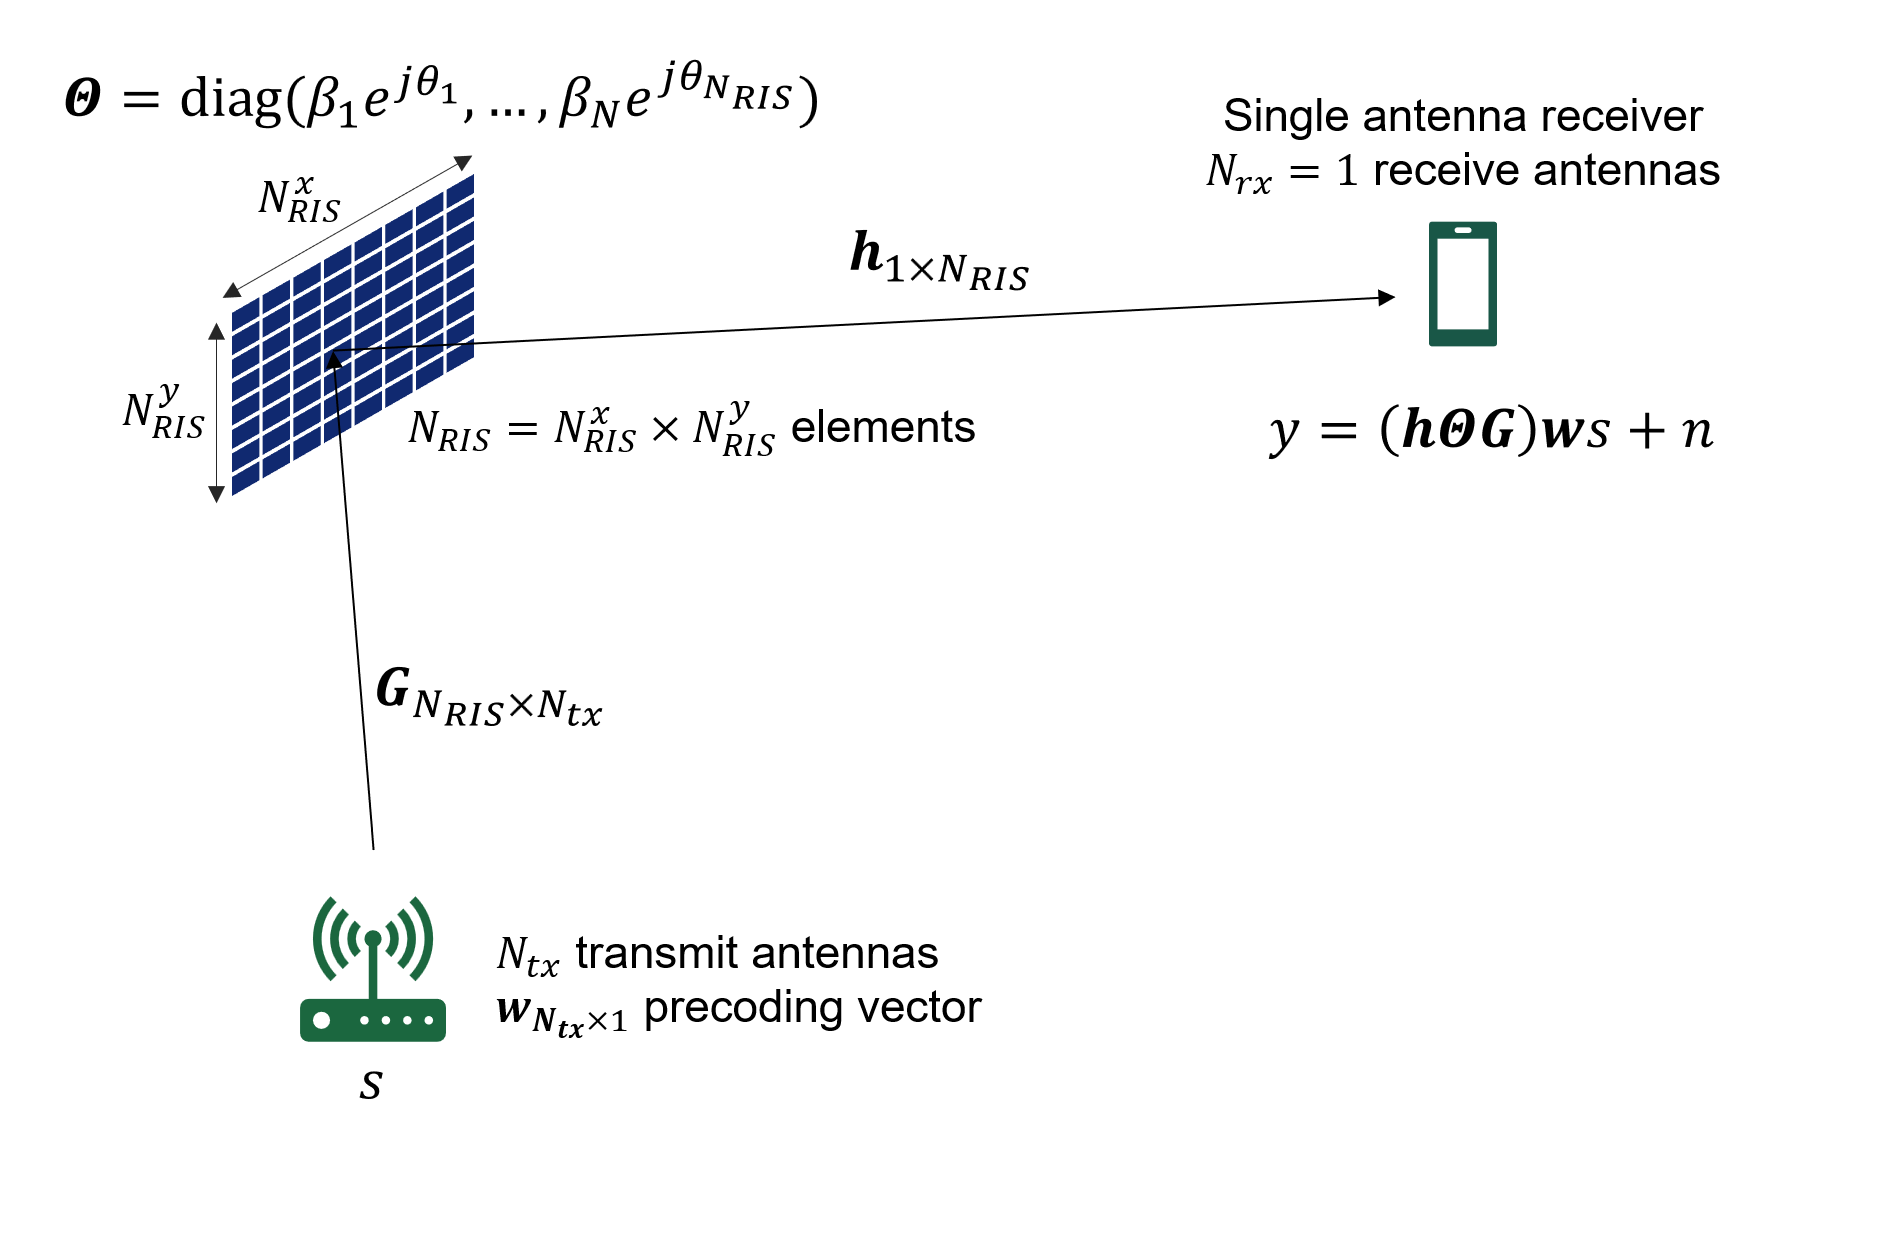

The example models both the channel between the transmitter and the RIS and the channel between the RIS and the receiver using CDL channels. To model the RIS, the example applies a phase rotation $\theta_i \;$ to each RIS element between both CDL channels. An iterative algorithm calculates the value of the phase shifts $\theta_i \;$assuming knowledge of channel matrices $\mathit{\mathbf{G}}$ and $\mathit{\mathbf{h}}$. This example also models path loss and the RIS scattering loss.

Where appropriate, the example uses parameters as defined in the group report from ETSI on RIS [1].

This example models the RIS with a stochastic channel model. For an introduction to RIS using a deterministic channel model, see the [Introduction to Reconfigurable Intelligent Surfaces (RIS)](docid:phased_ug#example-ex79865743) example.

## Set Carrier and PDSCH Parameters

Set the carrier frequency, carrier configuration object, and PDSCH parameters. Calculate the sampling rate of the signal of interest.

**PDSCH** sta per **Physical Downlink Shared Channel**. È un canale utilizzato nelle reti di comunicazione LTE e 5G per trasmettere dati utente dal nodo base agli utenti. Il PDSCH è responsabile della trasmissione dei dati principali e sfrutta le risorse di frequenza e tempo assegnate dinamicamente per ottimizzare l'efficienza della rete.

rng('default') %Imposta il generatore di numeri casuali di MATLAB al suo stato predefinito. Questo garantisce che i risultati siano riproducibili.

fc = 28e9; % Carrier frequency (Hz) 28*10^9 siamo in GHz
carrier = pre6GCarrierConfig("NSizeGrid",50,"SubcarrierSpacing",120); %Configura un oggetto carrier con una griglia di risorse di dimensione 50 e una spaziatura dei sottoportanti di 120 kHz, che è comune nelle comunicazioni ad alta frequenza.
pdsch = pre6GPDSCHConfig("Modulation","16QAM","NumLayers",1,"PRBSet",0:carrier.NSizeGrid-1); %Configura l'oggetto PDSCH per la trasmissione dati con modulazione 16-QAM (ovvero i 16 cluster che vedo nell'immagine), un singolo strato di trasmissione e usa tutte le risorse della griglia di PRB (Physical Resource Block).

ofdmInfo = hpre6GOFDMInfo(carrier); %Calcola le informazioni OFDM (Orthogonal Frequency-Division Multiplexing) basate sulla configurazione del carrier. Questo include dettagli come la larghezza di banda e la frequenza di campionamento.
fs = ofdmInfo.SampleRate; %Estrae la frequenza di campionamento dalla struttura di informazioni OFDM.

## Set RIS and Transmit Array Parameters

The example assumes a multi-antenna transmitter, $N_{\textrm{RIS}}$ RIS elements, and a single-antenna receiver. The single-antenna receiver assumption simplifies the RIS control algorithm. 

Specify the size of the transmit array. Use the format $\left\lbrack \begin{array}{ccccc}
M & N & P & M_g  & N_g 
\end{array}\right\rbrack$, where $M$ and $N$ are the number of rows and columns in the antenna array, respectively. $P$ is the number of polarizations (1 or 2). $M_g$ and $N_g$ are the number of row and column array panels, respectively. Perchè lo faccio? **Questo setup è utilizzato per configurare un array di antenne multi-antenna che può trasmettere con diverse polarizzazioni e distribuire il segnale in vari pannelli.**

**Numero di Polarizzazioni (P)**:

- **1 Polarizzazione**: L'antenna trasmette o riceve solo in una direzione di polarizzazione (ad esempio, solo orizzontale o solo verticale).

- **2 Polarizzazioni**: L'antenna può trasmettere o ricevere in due direzioni di polarizzazione ortogonali (ad esempio, sia orizzontale che verticale), il che aumenta la capacità e la robustezza della trasmissione.

**Mg e Ng**:

- **Mg (Number of Row Panels)**: Rappresenta il numero di pannelli dell'array distribuiti lungo le righe. Aumentare Mg consente una maggiore copertura e diversità spaziale.

- **Ng (Number of Column Panels)**: Rappresenta il numero di pannelli dell'array distribuiti lungo le colonne. Aumentare Ng permette una migliore gestione della direzione del segnale e del fascio.

Calcolo ora il numero totale di elementi dell'antenna nel trasmettitore:

% Transmit array
txArraySize = [4 2 2 1 1]; % [M N P Mg Ng], uso 2 polarizzazioni
Ntx =  prod(txArraySize(1:3)); %Questa linea calcola il numero totale di elementi dell'antenna nel trasmettitore moltiplicando M, N e P: ovvero fa 16 elementi totali dell'antenna trasmittente.

Set `ris.Enable` to `true` to enable the RIS element phase optimization algorithm. Disabling this flag assigns random phase shifts to each RIS element, therefore disabling the desired operation of the RIS. Specify the number of elements in the RIS, their dimensions $d_x$ and $d_y$, and the element gain $A$. The size of the RIS is$\left\lbrack \begin{array}{ccc}
N_{\textrm{RIS}}^y  & N_{\textrm{RIS}}^x  & P_{\textrm{RIS}} 
\end{array}\right\rbrack$, where $P_{\textrm{RIS}}$ is the number of polarizations per RIS element (1 or 2). Se questa flag è disabilitata (`ris.Enable = false`), vengono assegnati dei cambi di fase casuali agli elementi RIS (non uso l'algoritmo iterativo). Questo significa che il RIS non opererà nel modo desiderato, rendendo inefficace la sua funzione di ottimizzazione del segnale.

**Specificare i Parametri del RIS**:

- **Numero di Elementi**: Determina quanti elementi compongono il RIS.

- **Dimensioni dx e dy**: Specificano le dimensioni fisiche di ciascun elemento del RIS in due direzioni ortogonali.

- **Guadagno dell'Elemento A**: Rappresenta il guadagno del singolo elemento del RIS, che influisce sulla potenza del segnale riflesso.

Il codice qua sotto configura un sistema RIS per ottimizzare la riflessione del segnale in un ambiente di comunicazione wireless, migliorando la copertura, l'efficienza energetica e altre metriche di performance:

% RIS parameters 
ris.Enable = true;
ris.Size = [8 4 2]; %definisce le dimensioni dell'array RIS: 8 righe, 4 colonne, e 2 polarizzazioni.
numRISElements = prod(ris.Size); %calcola il numero totale di elementi del RIS (8 * 4 * 2 = 64).

% Wavelength
c = physconst("lightspeed");% c è la velocità della luce. 
lambda = c/fc;  % lambda calcola la lunghezza d'onda del segnale basata sulla frequenza del carrier fc.

% RIS element size
ris.dx = lambda/5; %ris.dx e ris.dy definiscono le dimensioni fisiche degli elementi RIS, impostate a un quinto della lunghezza d'onda.
ris.dy = lambda/5;

ris.A = 0.8; % imposta l'ampiezza dei coefficienti di riflessione per ciascun elemento del RIS, che influisce sulla potenza del segnale riflesso.

## Define RIS-Assisted Channel

This example models the propagation channel with two concatenated CDL channels. A phase rotation per RIS element between the CDL channels models the RIS. The `hpre6GRISChannel` object implements both CDL channels and the phase rotation per phase element. The `hpre6GRISChannel` class does not model the path loss, which is applied externally.

**Riproducibilità nella Simulazione**

**Riproducibilità** in questo contesto si riferisce alla capacità di eseguire la simulazione più volte e ottenere gli stessi risultati. Questo è cruciale per verificare e confrontare i risultati, garantendo che qualsiasi variazione osservata sia dovuta a cambiamenti nei parametri di simulazione e non a variazioni casuali.

risCh = hpre6GRISChannel("SampleRate",ofdmInfo.SampleRate,"RISSize",ris.Size,"CarrierFrequency",fc); %Crea un oggetto canale RIS (risCh) con il campionamento specificato (ofdmInfo.SampleRate), la dimensione del RIS (ris.Size), e la frequenza del carrier (fc).
risCh.TransmitAntennaArray.Size = txArraySize; %Imposta la dimensione dell'array di antenne di trasmissione (txArraySize).
risCh.ReceiveAntennaArray.Size = [1 1 1 1 1]; % Imposta la dimensione dell'array di antenne di ricezione a una singola antenna, come specificato nell'esempio.
risCh.Seed = randi([0,(2^32)-1]);             % Genera un seed casuale per la simulazione del canale, garantendo la riproducibilità

% Calculate the overall channel delay
%chInfo: Ottiene le informazioni del canale RIS.
%channelDelay: Calcola il ritardo complessivo del canale sommando il ritardo massimo tra il trasmettitore e il RIS (TxRISChInfo.MaximumChannelDelay) e il ritardo massimo tra il RIS e il ricevitore (RISRXChInfo.MaximumChannelDelay).
chInfo = risCh.info;
channelDelay = chInfo.TxRISChInfo.MaximumChannelDelay + chInfo.RISRXChInfo.MaximumChannelDelay;

Specify the transmit power, noise, and interference-related parameters, as defined in the group report from ETSI on RIS [1].

La densità del rumore termico è una misura del rumore generato dalla radiazione termica in un sistema di comunicazione elettronica. È espressa in dBm/Hz (decibel milliwatt per hertz) e rappresenta la potenza del rumore termico per unità di larghezza di banda. il suo valore tipico è appunto −174dBm/Hz.

Il codice qua sotto fornisce una stima accurata della potenza del rumore totale nel sistema, che è essenziale per calcolare il rapporto segnale-rumore (SNR) e ottimizzare le configurazioni del sistema.

txPower = 20;                                % dBm. Imposta la potenza media di trasmissione per antenna a 20 dBm.
% Noise and interference parameters
noiseFigure = 7;                             % dB Rappresenta la figura di rumore del ricevitore in dB.
thermalNoiseDensity = -174;                  % dBm/Hz Densità del rumore termico, tipicamente -174 dBm/Hz.
rxInterfDensity = -165.7;                    % dBm/Hz Densità di potenza dell'interferenza ricevuta in dBm/Hz.

% Calculate the corresponding noise power
totalNoiseDensity = 10*log10(10^((noiseFigure+thermalNoiseDensity)/10)+10^(rxInterfDensity/10)); %calcolo della potenza del rumore totale, Converte le densità di potenza del rumore e dell'interferenza in scala lineare, le somma e poi le riconverte in dBm.
BW = 12*carrier.NSizeGrid*carrier.SubcarrierSpacing*1e3; % Calcola la larghezza di banda totale del canale, basata sul numero di risorse di banda (NSizeGrid) e sulla spaziatura dei sottoportanti (SubcarrierSpacing).
noisePower = totalNoiseDensity+10*log10(BW); % Converte la densità di rumore totale in potenza del rumore sulla larghezza di banda totale in dBm.
N = 10^((noisePower-30)/10);                 % Linear = Converte la potenza del rumore da dBm a watt (scala lineare).

## Calculate RIS Link Path Loss

The path loss for a RIS scenario in the far field case is given in the ETSI report as:


$${\textrm{PL}}_{\textrm{RIS}} =\frac{64\pi^3 {\left(d_t d_r \right)}^2 }{G_t G_r G_s N_{\textrm{RIS}}^2 d_x d_y \lambda^2 F\left(\theta_t ,\phi_t \right)F\left(\theta_r ,\phi_r \right)A^2 }$$


$G_t$ and $G_r$ are the transmit and receive antenna gains. $G_s$ is the scattering gain of a single RIS element. $d_x$ and $d_y$ represent the width and length of each RIS element. $\lambda$ is the wavelength. $F\left(\theta_t ,\phi_t \right)$ and $F\left(\theta_r ,\phi_r \right)$ represent the normalized radiation pattern of each element in the direction of the transmitter and the receiver, respectively. $\theta_t$ and $\phi_t$ are the elevation and azimuth angles from the center of the RIS to the transmitter. $A$ represents the amplitude of reflection coefficients of each RIS element. It is assumed to be the same for all elements.

A common assumption of RIS element scattering gain is:


$$G_s =\frac{4\pi d_x d_y }{\lambda^2 }$$


This example assumes $G_t =G_r =F\left(\theta_t ,\phi_t \right)=F\left(\theta_r ,\phi_r \right)=1$. Therefore:


$${\textrm{PL}}_{\textrm{RIS}} =\frac{64\pi^3 {\left(d_t d_r \right)}^2 }{G_s N_{\textrm{RIS}}^2 d_x d_y \lambda^2 A^2 }={\left(\frac{4\pi d_t d_r }{N_{\textrm{RIS}} d_x d_y A}\right)}^2$$


% Distance between Tx and RIS and RIS and Rx
dt = 105; % Distanza tra il trasmettitore (Tx) e la RIS in metri.
dr = 7;   % Distanza tra la RIS e il ricevitore (Rx) in metri.

% Path loss (power gain)
PL = ((4*pi*dt*dr)/(prod(ris.Size(1:3))*ris.dx*ris.dy*ris.A)).^2;
%4pidt*dr: Fattore di propagazione che considera le distanze dal trasmettitore al RIS e dal RIS al ricevitore.
%prod(ris.Size(1:3)): Numero totale di elementi nel RIS.
%ris.dx e ris.dy: Dimensioni fisiche di ciascun elemento del RIS.
%ris.A: Ampiezza dei coefficienti di riflessione per ciascun elemento del RIS.
%PL: Potenza del segnale ridotta a causa della distanza e della configurazione del RIS.

disp("RIS link path loss "+10*log10(PL)+" dB") %Converte la perdita di percorso in dB e visualizza il risultato.

RIS link path loss 151.8968 dB


## Calculate Precoding Vector and RIS Elements Phase Value

**Precoding Vector**

Un **Precoding Vector** è un vettore utilizzato nei sistemi di comunicazione MIMO (Multiple Input Multiple Output) per pre-elaborare il segnale trasmesso, ottimizzando la trasmissione del segnale in presenza di canali multipath. Serve a migliorare l'efficienza dello spettro e la qualità del segnale, riducendo l'interferenza inter-canale e massimizzando il throughput del sistema.

This example uses a sub-optimal iterative approach to calculate the precoding vector $\mathit{\mathbf{w}}$ and phase values $\theta_i$. This approach is an iterative algorithm similar to the one described by Tao Zhou and Kui Xu [2]. For an initial set of phases $\theta_i$, the algorithm calculates the set of precoding weights $\mathit{\mathbf{w}}$ using maximum ratio transmission (MRT). Given the value of the precoding weights, the algorithm recalculates the set of phases $\theta_i$ such that the combined phase changes of both channels $\mathit{\mathbf{G}}$ and $\mathit{\mathbf{h}}$, and the RIS, are constant. This process repeats iteratively until the values converge to a solution. This algorithm guarantees at least a locally optimal solution.

**Utilità del codice sotto:**

- **Ottimizzazione del Sistema**: Migliora la qualità del segnale ricevuto ottimizzando i coefficienti degli elementi RIS.

- **Calcolo del Precoding**: Determina il miglior vettore di precoding per la trasmissione del segnale.

- **Analisi del Canale**: Fornisce una rappresentazione completa del canale, inclusi gli effetti del RIS, per una simulazione accurata delle prestazioni del sistema.

[risElementCoeff,w,overallChannel] = calculateRISCoeff(ris.Enable,risCh,carrier);

% Funzione calculateRISCoeff:
% Questa funzione calcola i coefficienti degli elementi RIS, i pesi e il canale complessivo basato su vari parametri di ingresso.
% 
% Parametri di Ingresso:
% ris.Enable: Indica se l'ottimizzazione della fase degli elementi RIS è abilitata o disabilitata.
% risCh: Oggetto del canale RIS, che contiene le informazioni sulla propagazione del segnale tra il trasmettitore, il RIS e il ricevitore.
% carrier: Configurazione del carrier, che include parametri come la frequenza del segnale e la spaziatura dei sottoportanti.
% 
% Parametri di Uscita:
% risElementCoeff: Coefficienti di riflessione degli elementi RIS. Questi determinano come il segnale viene riflesso dagli elementi del RIS.
% w: Pesi utilizzati per il precoding o altre operazioni di ottimizzazione del segnale.
% overallChannel: Il canale complessivo risultante dalla combinazione del canale trasmettitore-RIS e RIS-ricevitore.

To calculate the values of $\mathit{\mathbf{G}}$ and $\mathit{\mathbf{h}}$, this example calculates an average of the channel conditions over all subcarriers and OFDM symbols. 

**OFDM (Orthogonal Frequency-Division Multiplexing)**

**Definizione:**OFDM è una tecnica di modulazione digitale che divide un canale di comunicazione in diversi sottoportanti ortogonali. Ogni sottoportante trasmette una parte del segnale complessivo, migliorando l'efficienza spettrale e la robustezza contro interferenze e multipath.

***Caratteristiche Principali:***

**Ortogonalità**:

- Le sottoportanti sono ortogonali, riducendo l'interferenza tra di esse.

**Sottoportanti**:

- Il segnale è suddiviso in molte sottoportanti a bassa velocità, trasmesse in parallelo.

**Efficienza Spettrale**:

- Utilizza efficientemente la larghezza di banda disponibile.

**Robustezza**:

- Maggiore robustezza contro il fading e le interferenze rispetto ad altre tecniche di modulazione.

***Vantaggi:***

**Resistenza al Fading**:

- OFDM è meno sensibile al fading selettivo, comune in ambienti con molti ostacoli.

**Riduzione dell'Interferenza**:

- L'uso di sottoportanti ortogonali riduce l'interferenza inter-simbolo (ISI).

**Efficienza Spettrale**:

- Massimizza l'uso della larghezza di banda disponibile.

Check the convergence of the RIS phase calculation algorithm and plot the achievable SNR per iteration.

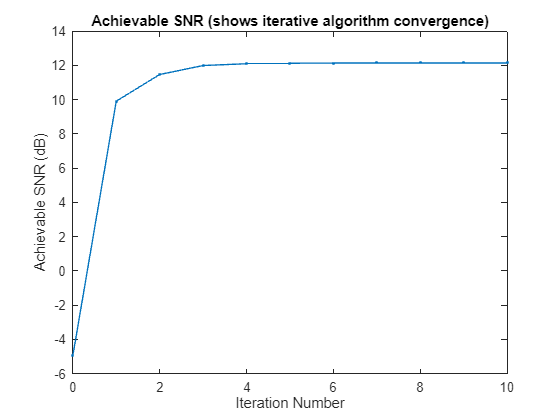

if ris.Enable %Verifica se il RIS è abilitato. Se ris.Enable è vero, esegue il blocco di codice seguente.
    % Consider tx array gain for the transmit power
    % (txPower is measured per antenna element)
    %calcolo dell'snr raggiungibile:
    achievableSNR = (txPower)+10*log10(Ntx)-10*log10(PL)+10*log10(abs(overallChannel).^2)-(noisePower);  
    % txPower: Potenza di trasmissione per elemento dell'antenna, in dBm.
    % 10*log10(Ntx): Guadagno dell'array di trasmissione, dove Ntx è il numero totale di elementi dell'antenna.
    % -10*log10(PL): Perdita di percorso (path loss) calcolata precedentemente.
    % 10*log10(abs(overallChannel).^2): Guadagno di potenza del canale complessivo, dove overallChannel rappresenta il canale ottimizzato.
    % - (noisePower): Potenza del rumore totale, in dBm.

    %tracciamento dell'snr raggiungibile:
    plot(0:length(achievableSNR)-1,achievableSNR,'.-')
    xlabel("Iteration Number");ylabel("Achievable SNR (dB)")
    title("Achievable SNR (shows iterative algorithm convergence)")
    % plot: Traccia il SNR raggiungibile per ogni iterazione dell'algoritmo.
    % xlabel: Etichetta per l'asse x ("Iteration Number").
    % ylabel: Etichetta per l'asse y ("Achievable SNR (dB)").
    % title: Titolo del grafico che indica che mostra la convergenza dell'algoritmo iterativo.
end

## Transmit and Receive Data

Generate one slot of a 6G-like frame and send it through the RIS-assisted channel. This example uses PDSCH uncoded bits (no channel coding, quindi la sicurezza viene meno). You can change the bandwidth and subcarrier spacing of this signal to explore the effect of RIS on 6G-like signals. 

% Trasposizione del Vettore di Precoding:
w = w.'; % transmitter requires w to be of the form number of layers by number of transmit antennas
% w: Vettore di precoding.
% w.': Traspone il vettore di precoding per conformarsi al formato richiesto dal trasmettitore, che è il numero di strati per il numero di antenne di trasmissione.

% Generazione della Forma d'Onda di Trasmissione:
[txWaveform,pdschSym,pdschInd,dmrsSym,dmrsInd,~,pdschGrid] = generateTxWaveform(carrier,pdsch,w,txPower);
% generateTxWaveform: Funzione che genera la forma d'onda di trasmissione basata sui parametri forniti.
% carrier: Configurazione del carrier.
% pdsch: Configurazione del PDSCH (Physical Downlink Shared Channel).
% w: Vettore di precoding trasposto.
% txPower: Potenza di trasmissione.

% Output della Funzione:
% 
% txWaveform: Forma d'onda di trasmissione generata.
% pdschSym: Simboli PDSCH generati.
% pdschInd: Indici dei simboli PDSCH.
% dmrsSym: Simboli DM-RS (Demodulation Reference Signal) generati.
% dmrsInd: Indici dei simboli DM-RS.
% ~: Output ignorato.
% pdschGrid: Griglia dei simboli PDSCH.

Send the signal through the channel and add noise.

Ovvero, Il codice seguente esegue una serie di operazioni per trasmettere un segnale attraverso un canale assistito da RIS, applicare la perdita di percorso, aggiungere rumore e misurare la potenza trasmessa e ricevuta.

% Pad with zeros to flush full slot from the channel, Aggiunge zeri alla fine della forma d'onda di trasmissione per compensare il ritardo del canale, garantendo che l'intera slot sia inviata attraverso il canale.
% il Padding con Zeri Garantisce che l'intera slot di trasmissione venga considerata nella simulazione del canale.
txWaveform = [txWaveform; zeros(channelDelay,size(txWaveform,2))]; 

% Send signal through RIS assisted channel, Il segnale trasmesso viene inviato attraverso il canale assistito da RIS, utilizzando i coefficienti degli elementi RIS calcolati.
rxWaveformNoisless = risCh(txWaveform,risElementCoeff);

% Apply path loss, Applica la perdita di percorso calcolata (path loss) al segnale ricevuto, riducendo l'ampiezza del segnale in funzione della distanza e delle caratteristiche del canale.
rxWaveformNoisless = (1/sqrt(PL))* rxWaveformNoisless;

% Add noise, Genera rumore gaussiano bianco additivo (AWGN) con una potenza calcolata e lo aggiunge al segnale ricevuto senza rumore per simulare un ambiente realistico.
noise = sqrt(N)*randn(size(rxWaveformNoisless),"like",rxWaveformNoisless);
rxWaveform = rxWaveformNoisless+noise; 

% Power measurements
% Ptx: Calcola la potenza media del segnale trasmesso per antenna in dBm.
% Prx: Calcola la potenza media del segnale ricevuto senza rumore per antenna in dBm.
% SNR: Calcola il rapporto segnale-rumore (SNR) nel dominio del tempo e lo visualizza in dB.
Ptx = mean(rms(txWaveform).^2);
Prx = mean(rms(rxWaveformNoisless).^2);
disp("Avg tx power (per antenna) = "+(10*log10(Ptx)+30)+" dBm")

Avg tx power (per antenna) = 19.9955 dBm


disp("Avg rx power (per antenna) = "+(10*log10(Prx)+30)+" dBm")

Avg rx power (per antenna) = -72.5773 dBm


disp("SNR (time domain) = "+10*log10(mean(rms(rxWaveformNoisless).^2)/mean(rms(noise).^2))+" dB")

SNR (time domain) = 12.1343 dB


Decode the received signal and plot the equalized constellation.

- **Sincronizzazione Perfetta**: Allinea correttamente il segnale ricevuto per garantire una decodifica accurata.

- **Decodifica PDSCH**: Estrae i dati utili dal segnale ricevuto, utilizzando simboli di riferimento per migliorare la precisione.

- **Visualizzazione dei Simboli**: Aiuta a valutare la qualità del segnale equalizzato e l'efficacia del sistema di comunicazione.

- **Calcolo del SNR per Elemento Risorsa**: Fornisce una misura dettagliata del rapporto segnale-rumore per ciascun elemento risorsa nel sistema OFDM, che è cruciale per valutare la qualità della comunicazione.

- **Normalizzazione rispetto ai punti FFT**: Assicura che i calcoli tengano conto della configurazione specifica del sistema OFDM, fornendo risultati accurati e pertinenti.

- **Visualizzazione del SNR**: Mostra chiaramente il SNR per elemento risorsa, permettendo di monitorare e ottimizzare le prestazioni del sistema di comunicazione.

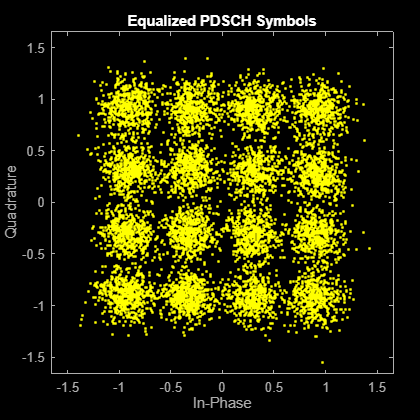

% Perfect synchronization:
% risCh.channelResponse(carrier): Calcola la risposta del canale RIS per il carrier specificato.
% offsetTxRIS e offsetRISRx: Offsets di sincronizzazione tra trasmettitore e RIS, e tra RIS e ricevitore.
% rxWaveform: Aggiorna il segnale ricevuto eliminando i campioni di offset, sincronizzando perfettamente il segnale.
[~,~,offsetTxRIS,offsetRISRx] = risCh.channelResponse(carrier);
rxWaveform = rxWaveform(1+offsetTxRIS+offsetRISRx:end,:);

% PDSCH decoding:
% decodePDSCH: Funzione che decodifica il canale PDSCH dal segnale ricevuto.
% rxWaveform: Segnale ricevuto sincronizzato.
% carrier: Configurazione del carrier.
% pdsch: Configurazione del PDSCH.
% pdschInd: Indici dei simboli PDSCH.
% dmrsSym e dmrsInd: Simboli e indici del segnale di riferimento per la demodulazione (DM-RS).
% pdschEq: Simboli PDSCH equalizzati.
% pdschRx: Simboli PDSCH ricevuti.
[pdschEq,pdschRx] = decodePDSCH(rxWaveform,carrier,pdsch,pdschInd,dmrsSym,dmrsInd);

% Visualizzazione dei Simboli Equalizzati:
% scatterplot(pdschEq): Visualizza un diagramma a dispersione dei simboli PDSCH equalizzati.
% title("Equalized PDSCH Symbols"): Imposta il titolo del grafico.
scatterplot(pdschEq); title("Equalized PDSCH Symbols")

%Il codice seguente calcola il rapporto segnale-rumore (SNR) per resource element (RE) e visualizza il risultato in dB:

%Calcolo della Potenza del Segnale per RE:
% ofdmInfo.Nfft: Numero di punti FFT (Fast Fourier Transform).
% rms(pdschRx): Valore quadratico medio (RMS) dei simboli PDSCH ricevuti.
% (1/ofdmInfo.Nfft.^2): Fattore di normalizzazione per la potenza del segnale distribuita su tutti i punti FFT.
% Sre: Potenza del segnale per resource element (RE).
Sre = (1/ofdmInfo.Nfft.^2)*rms(pdschRx).^2;

%Calcolo della Potenza del Rumore per RE:
% rms(noise): Valore quadratico medio (RMS) del rumore.
% (1/ofdmInfo.Nfft): Fattore di normalizzazione per la potenza del rumore distribuita su tutti i punti FFT.
% Nre: Potenza del rumore per resource element (RE).
Nre = (1/ofdmInfo.Nfft)*rms(noise).^2;

%Calcolo e Visualizzazione del SNR per Elemento Risorsa (RE):
%Sre/Nre: Rapporto tra la potenza del segnale e la potenza del rumore per singolo elemento risorsa.
% pow2db(Sre/Nre): Converte il rapporto segnale-rumore in dB.
% disp: Visualizza il SNR per elemento risorsa in dB.
disp("SNR (per RE) = " + string(pow2db(Sre/Nre)) + " dB");

SNR (per RE) = 14.7863 dB


Calculate the error vector magnitude (EVM) of the received signal.

- **Misura della Qualità del Segnale**: L'EVM è una metrica chiave per valutare la qualità del segnale ricevuto, essenziale per l'analisi delle prestazioni del sistema di comunicazione.

- **Diagnosi di Problemi**: Un EVM elevato può indicare problemi nel sistema, come interferenze, rumore, o imperfezioni nella modulazione/demodulazione, permettendo di identificare e risolvere eventuali problemi.

- **Ottimizzazione del Sistema**: Utilizzando l'EVM, è possibile ottimizzare i parametri del sistema di comunicazione per migliorare la qualità del segnale e ridurre gli errori di trasmissione.

%Creazione dell'Oggetto EVM:
%comm.EVM(): Crea un oggetto EVM utilizzando il toolbox di comunicazione di MATLAB. L'oggetto EVM calcola l'Error Vector Magnitude, una misura della qualità del segnale ricevuto rispetto al segnale trasmesso.
evm = comm.EVM();

%Calcolo dell'EVM dei Simboli PDSCH:
% pdschSym: Simboli PDSCH trasmessi.
% pdschEq: Simboli PDSCH equalizzati ricevuti.
% evm(pdschSym, pdschEq): Calcola l'EVM dei simboli PDSCH, confrontando i simboli ricevuti ed equalizzati con i simboli trasmessi. L'EVM è espresso come percentuale.
symbolsEVM = evm(pdschSym,pdschEq);

%Visualizzazione dell'EVM:
%disp: Visualizza il valore dell'EVM calcolato come una percentuale, fornendo un'indicazione della qualità del segnale ricevuto. Un valore di EVM più basso indica una migliore qualità del segnale, mentre un valore più alto indica una maggiore distorsione o errore.
disp("PDSCH symbols EVM: "+symbolsEVM+"%") 

PDSCH symbols EVM: 19.3054%


## References

[1] ETSI GR RIS 003 V1.1.1. "Reconfigurable Intelligent Surfaces (RIS); Communication Models, Channel Models, Channel Estimation and Evaluation Methodology."

[2] Tao Zhou, Kui Xu. *Multi-Intelligent Reflecting Surface-Aided Wireless Network With Achievable Rate Maximization*. 2020 International Conference on Wireless Communications and Signal Processing (WCSP).

## Local Functions


%FUNZIONE 1: ovverto l'algoritmo iterativo usato per l'ottimizzazione dei
% coefficienti di riflessione della RIS.
% Questa funzione calcola i coefficienti degli elementi RIS, i pesi del precoding, e la risposta complessiva del canale.
% risElementCoeff: Coefficienti degli elementi RIS inizializzati con fasi casuali.
% w: Pesi del precoding calcolati usando Maximum Ratio Transmission.
% Htot: Matrice del canale complessiva per monitorare la convergenza.

function [risElementCoeff,w,Htot] = calculateRISCoeff(enableRIS,risCh,carrier)
    
    % Initialize RIS element coefficients (gain = 1 and random phase)
    numRISElements = prod(risCh.RISSize);
    theta = 2*pi*rand(1,numRISElements); % uniformly distributed phases in [0, 2*pi]
    risElementCoeff = exp(1i*theta);
    % If the RIS algorithm is disabled, this is the value used in the
    % simulation

    [G,h] = getRISChannelFreqResponse(risCh,carrier);

    H = h*diag(risElementCoeff)*G;

    % Calculate precoding weights using MRT (maximum ratio transmission)
    w = H'/norm(H);

    if enableRIS
        numIter = 10;  % Number of iterations
        Htot = zeros(numIter+1,1); % Total channel H*wf. Used to check convergence
        Htot(1) = H*w;
        for n = 1:numIter
            % Need to calculate B = h*diag(G*w), where w is the transmitter
            % precoding vector, G is the transmitter to RIS channel matrix and
            % h is the RIS to receiver channel matrix. B is used to calculate
            % the new RIS phase values theta as -angle(B)
            B = h*diag(G*w);

            % Calculate the new phase vector phi that compensates for the phase changes in hr, G and w
            theta = -angle(B);

            % New RIS coefficients
            risElementCoeff = exp(1i*theta); 

            % New combined channel matrix H
            H = h*diag(risElementCoeff)*G;            

            % Get new weights w based on new channel matrix H
            w = H'/norm(H);

            % Overall channel response for this iteration. Used to check
            % convergence
            Htot(n+1) = H*w;
        end
    else
        Htot = H*w;
    end
end

%FUNZIONE 2:
% Questa funzione calcola la risposta in frequenza del canale RIS, mediando la risposta del canale sull'intera larghezza di banda.
% G: Matrice del canale tra trasmettitore e RIS.
% h: Matrice del canale tra RIS e ricevitore.

function [G,h] = getRISChannelFreqResponse(risCh,carrier)
    % Calculate the overall RIS channel response averaging the 
    % channel response, that is, one channel matrix for the whole
    % bandwidth, and not per resource element. 
    [TxRISGrid,RISRxGrid] = channelResponse(risCh,carrier);
    
    h = zeros(size(RISRxGrid,3),size(RISRxGrid,4));
    RISRxGrid = mean(RISRxGrid,[1 2]); % assume flat in time and freq
    h(:,:) = RISRxGrid(1,1,:,:);

    G = zeros(size(TxRISGrid,3),size(TxRISGrid,4));
    TxRISGrid = mean(TxRISGrid,[1 2]); % assume flat in time and freq
    G(:,:) = TxRISGrid(1,1,:,:);
end

%FUNZIONE 3:
% Questa funzione genera la forma d'onda di trasmissione per il sistema, includendo la precodifica e la modulazione OFDM.
% txWaveform: Forma d'onda trasmessa generata.
% pdschSymbols: Simboli PDSCH generati e precodificati.
% dmrsSymbols: Simboli di riferimento DM-RS generati.
% pdschGrid: Griglia delle risorse che contiene i simboli PDSCH.

function [txWaveform,pdschSymbols,pdschIndices,dmrsSymbols,dmrsIndices,waveformInfo,pdschGrid] ...
    = generateTxWaveform(carrier,pdsch,wtx,txPower)

    nTxAnts = length(wtx);

    % PDSCH and PDSCH DM-RS
    [pdschIndices,pdschInfo] = hpre6GPDSCHIndices(carrier,pdsch);
    pdschBits = randi([0 1],pdschInfo.G,1);
    pdschSymbols = hpre6GPDSCH(carrier,pdsch,pdschBits);
    
    dmrsSymbols = hpre6GPDSCHDMRS(carrier,pdsch);
    dmrsIndices = hpre6GPDSCHDMRSIndices(carrier,pdsch);
    
    % PDSCH precoding
    pdschSymbolsPrecoded = pdschSymbols*wtx;
    
    % Grid
    pdschGrid = hpre6GResourceGrid(carrier,nTxAnts);
    
    [~,pdschAntIndices] = nrExtractResources(pdschIndices,pdschGrid);
    pdschGrid(pdschAntIndices) = pdschSymbolsPrecoded;
    
    % PDSCH DM-RS precoding and mapping
    for p = 1:size(dmrsSymbols,2)
        [~,dmrsAntIndices] = nrExtractResources(dmrsIndices(:,p),pdschGrid);
        pdschGrid(dmrsAntIndices) = pdschGrid(dmrsAntIndices) + dmrsSymbols(:,p)*wtx(p,:);
    end
    
    % OFDM Modulation
    [txWaveform,waveformInfo] = hpre6GOFDMModulate(carrier,pdschGrid);

    % Scale power of transmitted signal to desired value.
    txWaveform = scalePower(txWaveform,txPower);
end

%FUNZIONE 4:
% Questa funzione scala la potenza del segnale trasmesso per raggiungere il valore desiderato.
% waveform: Forma d'onda scalata per raggiungere la potenza desiderata.

function  waveform = scalePower(waveform,desiredPower)
    % Scale input WAVEFORM to achieve the desiredPower in dBm
    K = sqrt((1/mean(rms(waveform).^2))*10^((desiredPower-30)/10));
    waveform = K*waveform;
end

%FUNZIONE 5:
% Questa funzione decodifica il PDSCH dal segnale ricevuto, includendo la demodulazione OFDM e l'uguagliamento.
% rxGrid: Griglia delle risorse OFDM demodulata.
% pdschEq: Simboli PDSCH equalizzati.
% pdschRx: Simboli PDSCH ricevuti.

function [pdschEq,pdschRx] = decodePDSCH(rxWaveform,carrier,pdsch,pdschIndices,dmrsSymbols,dmrsIndices)
    
    % OFDM demodulation
    rxGrid = hpre6GOFDMDemodulate(carrier,rxWaveform);
    
    % Channel estimation
    [estChGridLayers,noiseEst] = hpre6GChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,...
        'CDMLengths',pdsch.DMRS.CDMLengths);
    
    % Equalization
    [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChGridLayers);
    [pdschEq,~] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);
end

%FUNZIONE 6:

function info = hpre6GOFDMInfo(carrier,varargin)

    narginchk(1,7);

    % Validate carrier input
    mustBeA(carrier,'pre6GCarrierConfig');

    % Parse options
    fcnName = 'hpre6GOFDMInfo';
    optNames = {'Nfft','Windowing','CarrierFrequency'};
    opts = nr5g.internal.parseOptions(fcnName,optNames,varargin{:});

    % Get OFDM information
    info = nrOFDMInfo(carrier,opts);

end


Copyright 2023-2024 The MathWorks, Inc.